In this example, given a robot with specific geometry (polytope, ellipsoid...) and a polytopic free region, we show how we construct and solve the proposed minimum scaling problem (6), (7) for given robot configuration $q$  and extract the gradient information, step by step.

The value of the scaling factor as well as the gradient information with respect to robot configurations can be further integrated with gradient-based trajectory optimization solvers to drive the robot inward the free region to ensure motion safety. 

You need to specify: 

- **free_region.V**: vertexes of the polytopic free region representation in wolrd frame.

- **f_robot**: robot geometry represented as a semi-algebriac set in Euclidean coordinate [x,y,z], e.g., polytope, ellipical cone......

- **state**: robot configuration [qx,qy,qz,roll,pitch,yaw].

You will obtain:

- **alpha: **minimum scaling factor of the free region to contain the robot with specific geometry.

- **dual_vector: **dual value corresponding to all the equality constaints (7a). 

- **eval_gradient_state: **gradient information that provides a guiding optimization direction of the robot configuration for decreasing the value of alpha to push the robot inward the free regions.

**STEP 1: INITIALIZE THE ENVIRONMENT**

addpath(genpath('./third_party/matlab/mosek/10.1/toolbox/r2017a'));
addpath(genpath('./third_party/matlab/mr'));
addpath(genpath('./third_party/matlab/bt-1.3'));
addpath('./utils/');

**STEP 2: DEFINE THE REPRESENTATIONS OF ROBOT AND FREE REGION **

syms x y z real
% ------------------- Define free region representation ------------------------------- %
% define the vertices of the polytopic free region and get its hyperplane representation in world frame
free_region.V = [4,7,0;6,7,0;8,6,0;9,1,0;2,1,0;2,3,0;4,7,-1;6,7,-1;8,6,-1;9,1,-1;2,1,-1;2,3,-1]';
free_region_poly_world = polyh(free_region, 'v');

% define the free region frame {q} free region, which is located at its geometrical center.
free_region_origin = sum(free_region.V,2)/size(free_region.V,2);
w_T_freeRegion = [eye(3),free_region_origin;0,0,0,1];

% generate free region representation in its own frame
free_region_poly_own = rep_poly_bTow(free_region_poly_world,TransInv(w_T_freeRegion));
h_free_region_poly_own = hrep(free_region_poly_own);
% F = hrep(free_region_poly_own).B, g = hrep(free_region_poly_own).b
% the free region representation in its own frame is: g - Fx >= 0
f_free_region_poly_own = h_free_region_poly_own.b - h_free_region_poly_own.B*[x,y,z]';

% ------------------- Define the robot representation ------------------------------- %
% here we use a polytope for example,  we could also replace it with other
% geometry provided it can be represented as a semi-algebraic set.
robot.V = [1,0,0;0,1,0;-1,0,0;0,-1,0;1,0,-0.5;0,1,-0.5;-1,0,-0.5;0,-1,-0.5]';
robot_poly_own = polyh(robot,'v');
h_robot_poly_own = hrep(robot_poly_own);
f_robot_b = round(h_robot_poly_own.b,6);
f_robot_B = round(h_robot_poly_own.B,6);
% robot represented as a semi-algebriac set
f_robot = f_robot_b - f_robot_B*[x,y,z]';
f_robot = vpa(f_robot,3);

% ---------------------- Input the current robot configuration -------------------------- %
% q = [qx,qy,qz,roll,pitch yaw]
qx = 5, qy = 2, qz = 2, roll = pi/4, pitch = 0, yaw = pi/3;

qx = 5

qy = 2

qz = 3

roll = 0.7854

pitch = 0

state = [qx,qy,qz,roll,pitch yaw];

% transformation matrix of the robot body frame represented in world
w_R_robot = rotz(yaw)*roty(pitch)*rotx(roll);
w_T_robot = [w_R_robot,state(1:3)';0,0,0,1];

% -------------- Visualize the free region and the robot in world frame ----------------- %
plot(free_region_poly_world); % plot free region
hold on;
opt_robot.color = [1,0,0];
robot_poly_world = rep_poly_bTow(robot_poly_own,w_T_robot) % robot representation in world frame

robot_poly_world =   polyh with properties:

     vrepdata: []
     hrepdata: []
      adjdata: []
      incdata: []
        empty: -1
    evaluated: 0
       lindim: -2
       objdim: -2


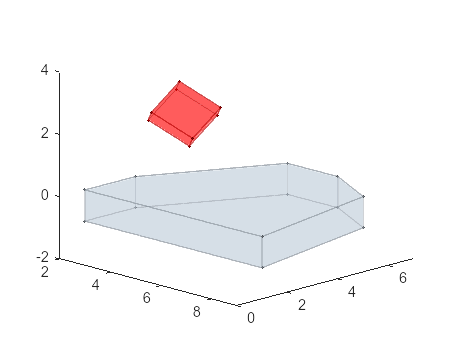

plot(robot_poly_world,opt_robot); % plot robot in red

**STEP 3: PROBLEM FORMULATION IN MOSEK**

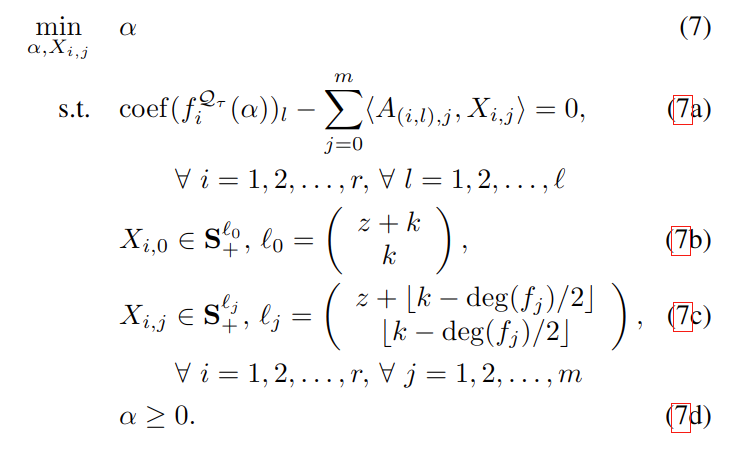

We model our proposed minimum scaling SDP optimization problem (7) following the convention of Mosek Semidefinite Optimization stated in the figure below, see also: [Mosek SDP Formulation](https://docs.mosek.com/latest/toolbox/tutorial-sdo-shared.html).

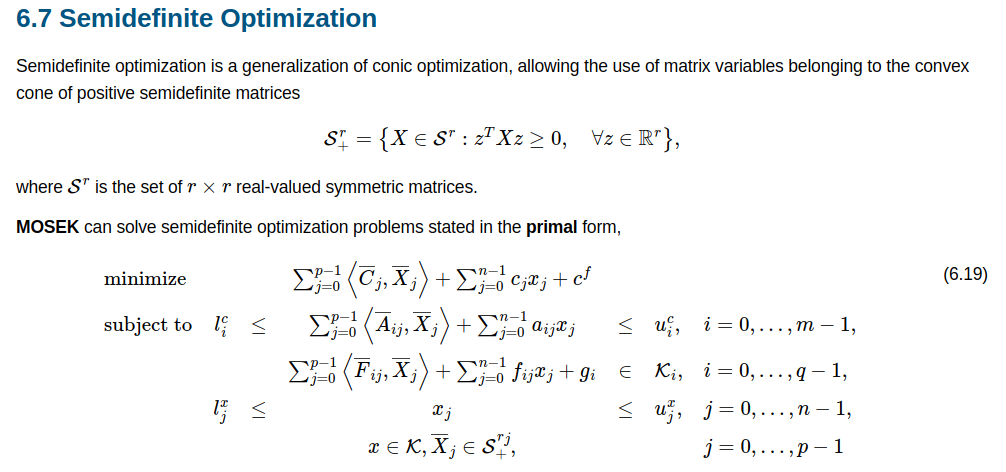

% ------------- Construct all the matrix coefficients Aij --------------- %
% total number of equalities constraints = number of facets in free region * number of monomials 
% total number of SDP variables X = (number of polynomial in robots +1) * number of facets in free region
% for each Aij, i: which constraint, j: which SDP variable

% we consider the 2k truncation of Qmod
deg_k = 0; % for polytopic shape robot, you can also use deg_k = 0
num_facets_free_region = size(f_free_region_poly_own,1);
num_polynomials_robot = size(f_robot,1);

% degree of polynomial functions in f_robot
deg_f_robot = polynomialDegree(f_robot,[x y z]);


dim_sos_matrix = zeros(num_facets_free_region,num_polynomials_robot+1); % store the degree of all the SOS multipliers
f_matrix = zeros(num_facets_free_region,num_polynomials_robot+1); % store all the polynomials in the 2k truncation of Qmod
f_matrix = sym(f_matrix);

% generate all the sos multipliers and the polynomials in Qmod. 
for m = 1:num_facets_free_region
 for n = 0:num_polynomials_robot
     name = strcat('X',num2str(m),'_',num2str(n));
     if n == 0
         [sos_multiplier,dim_sos,X] = gen_sos_polynomial(deg_k,[x,y,z],name);
         dim_sos_matrix(m,n+1) = dim_sos; 
         eval([name,'=X']);
         f_matrix(m,n+1) = sos_multiplier;
     else
         % decide degree of sos multiplier of each polynomial functions represented robot
         % Qmod_2k = sigma_2k + sigma_{2k-deg(fi_robot)}*fi_robot,
         deg = fix((2*deg_k - deg_f_robot(n))/2);
         [sos_multiplier,dim_sos,X] = gen_sos_polynomial(deg,[x,y,z],name);
         polynomial_in_Qmod = sos_multiplier * f_robot(n);
         dim_sos_matrix(m,n+1) = dim_sos;
         eval([name,'=X']);
         f_matrix(m,n+1) = polynomial_in_Qmod;
     end
 end
end

$$X1\_0 = X_{1,0,1,1}$$

$$X1\_1 = X_{1,1,1,1}$$

$$X1\_2 = X_{1,2,1,1}$$

$$X1\_3 = X_{1,3,1,1}$$

$$X1\_4 = X_{1,4,1,1}$$

$$X1\_5 = X_{1,5,1,1}$$

$$X1\_6 = X_{1,6,1,1}$$

$$X2\_0 = X_{2,0,1,1}$$

$$X2\_1 = X_{2,1,1,1}$$

$$X2\_2 = X_{2,2,1,1}$$

$$X2\_3 = X_{2,3,1,1}$$

$$X2\_4 = X_{2,4,1,1}$$

$$X2\_5 = X_{2,5,1,1}$$

$$X2\_6 = X_{2,6,1,1}$$

$$X3\_0 = X_{3,0,1,1}$$

$$X3\_1 = X_{3,1,1,1}$$

$$X3\_2 = X_{3,2,1,1}$$

$$X3\_3 = X_{3,3,1,1}$$

$$X3\_4 = X_{3,4,1,1}$$

$$X3\_5 = X_{3,5,1,1}$$

$$X3\_6 = X_{3,6,1,1}$$

$$X4\_0 = X_{4,0,1,1}$$

$$X4\_1 = X_{4,1,1,1}$$

$$X4\_2 = X_{4,2,1,1}$$

$$X4\_3 = X_{4,3,1,1}$$

$$X4\_4 = X_{4,4,1,1}$$

$$X4\_5 = X_{4,5,1,1}$$

$$X4\_6 = X_{4,6,1,1}$$

$$X5\_0 = X_{5,0,1,1}$$

$$X5\_1 = X_{5,1,1,1}$$

$$X5\_2 = X_{5,2,1,1}$$

$$X5\_3 = X_{5,3,1,1}$$

$$X5\_4 = X_{5,4,1,1}$$

$$X5\_5 = X_{5,5,1,1}$$

$$X5\_6 = X_{5,6,1,1}$$

$$X6\_0 = X_{6,0,1,1}$$

$$X6\_1 = X_{6,1,1,1}$$

$$X6\_2 = X_{6,2,1,1}$$

$$X6\_3 = X_{6,3,1,1}$$

$$X6\_4 = X_{6,4,1,1}$$

$$X6\_5 = X_{6,5,1,1}$$

$$X6\_6 = X_{6,6,1,1}$$

$$X7\_0 = X_{7,0,1,1}$$

$$X7\_1 = X_{7,1,1,1}$$

$$X7\_2 = X_{7,2,1,1}$$

$$X7\_3 = X_{7,3,1,1}$$

$$X7\_4 = X_{7,4,1,1}$$

$$X7\_5 = X_{7,5,1,1}$$

$$X7\_6 = X_{7,6,1,1}$$

$$X8\_0 = X_{8,0,1,1}$$

$$X8\_1 = X_{8,1,1,1}$$

$$X8\_2 = X_{8,2,1,1}$$

$$X8\_3 = X_{8,3,1,1}$$

$$X8\_4 = X_{8,4,1,1}$$

$$X8\_5 = X_{8,5,1,1}$$

$$X8\_6 = X_{8,6,1,1}$$

clear X;

f_matrix = vpa(f_matrix,3);
max_deg_equality_constraint = max(max(polynomialDegree(f_matrix,[x,y,z]))); % max degree
monomials_equality_constraints = mono_grevlex_fun([x,y,z],max_deg_equality_constraint); % generate all the monomials existing in the equalities constraints (7a)
num_monomials = size(monomials_equality_constraints,1);

% generate all Aij in the inner product <A,X>, and store all A in a container map.
A = containers.Map('KeyType','char','ValueType','any');
for m = 1:num_facets_free_region
    for i = 1:num_monomials % every constraint
        for n = 0:num_polynomials_robot
            index_i = num2str((m-1)*num_monomials+i); % i: which constraint
            index_j = num2str((m-1)*(num_polynomials_robot+1)+n);  % j: which SDP variable
            name = strcat('A','_', index_i,'_',index_j);
            % an util function that generate A{index_i}{index_j} corresponding to
            % the index_i constraint and index_j SDP variables
            [Aij,empty_flag] = generate_coeffs_matrix(f_matrix(m,n+1),eval(strcat('X',num2str(m),'_',num2str(n))), monomials_equality_constraints(i),[x,y,z]);
            if empty_flag == 0
                eval([name,'=Aij']);
                A(name) = eval(name);
            end
        end
    end
end

$$A\_1\_0 = 1$$

$$A\_1\_1 = 1.0$$

$$A\_1\_2 = 0.25$$

$$A\_1\_4 = 0.25$$

$$A\_1\_5 = 0.25$$

$$A\_1\_6 = 0.25$$

$$A\_2\_2 = 0.25$$

$$A\_2\_4 = -0.25$$

$$A\_2\_5 = -0.25$$

$$A\_2\_6 = 0.25$$

$$A\_3\_2 = 0.25$$

$$A\_3\_4 = -0.25$$

$$A\_3\_5 = 0.25$$

$$A\_3\_6 = -0.25$$

$$A\_4\_1 = 2.0$$

$$A\_4\_3 = -0.6666669999976875260472297668457$$

$$A\_5\_7 = 1$$

$$A\_5\_8 = 1.0$$

$$A\_5\_9 = 0.25$$

$$A\_5\_11 = 0.25$$

$$A\_5\_12 = 0.25$$

$$A\_5\_13 = 0.25$$

$$A\_6\_9 = 0.25$$

$$A\_6\_11 = -0.25$$

$$A\_6\_12 = -0.25$$

$$A\_6\_13 = 0.25$$

$$A\_7\_9 = 0.25$$

$$A\_7\_11 = -0.25$$

$$A\_7\_12 = 0.25$$

$$A\_7\_13 = -0.25$$

$$A\_8\_8 = 2.0$$

$$A\_8\_10 = -0.6666669999976875260472297668457$$

$$A\_9\_14 = 1$$

$$A\_9\_15 = 1.0$$

$$A\_9\_16 = 0.25$$

$$A\_9\_18 = 0.25$$

$$A\_9\_19 = 0.25$$

$$A\_9\_20 = 0.25$$

$$A\_10\_16 = 0.25$$

$$A\_10\_18 = -0.25$$

$$A\_10\_19 = -0.25$$

$$A\_10\_20 = 0.25$$

$$A\_11\_16 = 0.25$$

$$A\_11\_18 = -0.25$$

$$A\_11\_19 = 0.25$$

$$A\_11\_20 = -0.25$$

$$A\_12\_15 = 2.0$$

$$A\_12\_17 = -0.6666669999976875260472297668457$$

$$A\_13\_21 = 1$$

$$A\_13\_22 = 1.0$$

$$A\_13\_23 = 0.25$$

$$A\_13\_25 = 0.25$$

$$A\_13\_26 = 0.25$$

$$A\_13\_27 = 0.25$$

$$A\_14\_23 = 0.25$$

$$A\_14\_25 = -0.25$$

$$A\_14\_26 = -0.25$$

$$A\_14\_27 = 0.25$$

$$A\_15\_23 = 0.25$$

$$A\_15\_25 = -0.25$$

$$A\_15\_26 = 0.25$$

$$A\_15\_27 = -0.25$$

$$A\_16\_22 = 2.0$$

$$A\_16\_24 = -0.6666669999976875260472297668457$$

$$A\_17\_28 = 1$$

$$A\_17\_29 = 1.0$$

$$A\_17\_30 = 0.25$$

$$A\_17\_32 = 0.25$$

$$A\_17\_33 = 0.25$$

$$A\_17\_34 = 0.25$$

$$A\_18\_30 = 0.25$$

$$A\_18\_32 = -0.25$$

$$A\_18\_33 = -0.25$$

$$A\_18\_34 = 0.25$$

$$A\_19\_30 = 0.25$$

$$A\_19\_32 = -0.25$$

$$A\_19\_33 = 0.25$$

$$A\_19\_34 = -0.25$$

$$A\_20\_29 = 2.0$$

$$A\_20\_31 = -0.6666669999976875260472297668457$$

$$A\_21\_35 = 1$$

$$A\_21\_36 = 1.0$$

$$A\_21\_37 = 0.25$$

$$A\_21\_39 = 0.25$$

$$A\_21\_40 = 0.25$$

$$A\_21\_41 = 0.25$$

$$A\_22\_37 = 0.25$$

$$A\_22\_39 = -0.25$$

$$A\_22\_40 = -0.25$$

$$A\_22\_41 = 0.25$$

$$A\_23\_37 = 0.25$$

$$A\_23\_39 = -0.25$$

$$A\_23\_40 = 0.25$$

$$A\_23\_41 = -0.25$$

$$A\_24\_36 = 2.0$$

$$A\_24\_38 = -0.6666669999976875260472297668457$$

$$A\_25\_42 = 1$$

$$A\_25\_43 = 1.0$$

$$A\_25\_44 = 0.25$$

$$A\_25\_46 = 0.25$$

$$A\_25\_47 = 0.25$$

$$A\_25\_48 = 0.25$$

$$A\_26\_44 = 0.25$$

$$A\_26\_46 = -0.25$$

$$A\_26\_47 = -0.25$$

$$A\_26\_48 = 0.25$$

$$A\_27\_44 = 0.25$$

$$A\_27\_46 = -0.25$$

$$A\_27\_47 = 0.25$$

$$A\_27\_48 = -0.25$$

$$A\_28\_43 = 2.0$$

$$A\_28\_45 = -0.6666669999976875260472297668457$$

$$A\_29\_49 = 1$$

$$A\_29\_50 = 1.0$$

$$A\_29\_51 = 0.25$$

$$A\_29\_53 = 0.25$$

$$A\_29\_54 = 0.25$$

$$A\_29\_55 = 0.25$$

$$A\_30\_51 = 0.25$$

$$A\_30\_53 = -0.25$$

$$A\_30\_54 = -0.25$$

$$A\_30\_55 = 0.25$$

$$A\_31\_51 = 0.25$$

$$A\_31\_53 = -0.25$$

$$A\_31\_54 = 0.25$$

$$A\_31\_55 = -0.25$$

$$A\_32\_50 = 2.0$$

$$A\_32\_52 = -0.6666669999976875260472297668457$$


% ------------- Calculate the lower bound and upper bound, i.e., lc and uc. For equalities constraints, lc = uc --------------- %
b_free_region_own = round(h_free_region_poly_own.b,6);
B_free_region_own = round(h_free_region_poly_own.B,6);
freeRegion_T_robot = TransInv(w_T_freeRegion)*w_T_robot;
R = freeRegion_T_robot(1:3,1:3);
p = freeRegion_T_robot(1:3,4);
polyConstant_vector = vpa(-B_free_region_own*R*[x,y,z]'-B_free_region_own*p,3);  % free region in robot body frame
constant_value = zeros(num_facets_free_region*num_monomials,1); % same size with the number of constraints.
for i = 1:num_facets_free_region
    for j = 1:num_monomials
        index = num_monomials*(i-1) + j;
        constant_value(index) = coeffs_term(polyConstant_vector(i),monomials_equality_constraints(j),[x,y,z]); % extract the constant coefficients for each monomial
    end
end

% ------------------ Construct the problem --------------------------- %
prob.c = 1; % minimize alpha
% prob.barc = []; % no matrix terms in objective 

% coefficients of scalar variables in the constraints
num_equalities_constraints = num_facets_free_region * num_monomials;
num_scalar_variable = 1;
scalar_index_i = zeros(num_facets_free_region,1);
for i = 1:num_facets_free_region
    scalar_index_i(i) = (i-1)*num_monomials + 1; % scalar variable alpha only appears in the constraint related to the first monomial term of every free region facet 
end
prob.a = sparse(scalar_index_i,ones(num_facets_free_region,1),-b_free_region_own,num_equalities_constraints,num_scalar_variable);  % a sparse matrix (vector)

% specify bound of scalar variables: alpha >= 0 
prob.blx = 0;
prob.bux = inf;

% dimesions of PSD variables X
num_psd_variables = size(dim_sos_matrix,1)*size(dim_sos_matrix,2);
prob.bardim = reshape(dim_sos_matrix',1,num_psd_variables);

% coefficients of PSD variables in the constraints
% find sparse representation of A in this iteration.
keys = A.keys;
subi = [];
subj = [];
subk = [];
subl = [];
val = [];
for i = 1:A.Count
    str_split = split(string(keys{i}),'_');
    subi_current = str2double(str_split(end-1));
    subj_current = str2double(str_split(end))+1;
    [r,c,v] = find(tril(A(keys{i}))); 
    length_current = length(r);
    subi = [subi;repmat(subi_current,length_current,1)];
    subj = [subj;repmat(subj_current,length_current,1)];
    subk = [subk;r];
    subl = [subl;c];
    val = [val;v];
end
prob.bara.subi = subi;
prob.bara.subj = subj;
prob.bara.subk = subk;
prob.bara.subl = subl;
prob.bara.val = double(val);
% specify the constant bounds of the equalities constraints
prob.blc = constant_value';
prob.buc = constant_value';

**STEP 4: SOLVE THE PROBLEM USING MOSEK**

% ----------------- solve the problem and extract primal-dual optimum--------------- %
[r,res] = mosekopt('minimize echo(3) info',prob);

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 32              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 1               
  Matrix variables       : 56 (scalarized: 56)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - primal

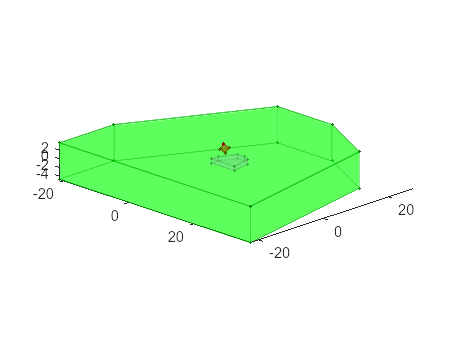

% extract primal-dual optimal solutions.
alpha = res.sol.itr.xx;
dual_vector = res.sol.itr.suc-res.sol.itr.slc; % dual values of corresponding to the equality constraints (7a)

% ----------------- visualize the scaled free region --------------- %
% the scaled free region is shown in green, we have calculated the minimum scaling factor such that the robot
% is contained in the scaled free region.
h_free_region_poly_own_scaling.b = h_free_region_poly_own.b*alpha;
h_free_region_poly_own_scaling.B = h_free_region_poly_own.B;
free_region_poly_own_scaling = polyh(h_free_region_poly_own_scaling,'h');
opt_scaling.color = [0,1,0];
free_region_poly_world_scaling = rep_poly_bTow(free_region_poly_own_scaling,w_T_freeRegion);
plot(free_region_poly_world_scaling,opt_scaling);
axis equal;

**STEP 5: EXTRACT THE GRADIENT**

% --------------- gradient of Lagaragian with respect to robot configuration at primal-dual optimum ------------- % 
load('gradient_expression.mat');% the analytical expression of the gradients, obtained by running "calculate_gradients.m"
% robot state 
x_value = state(1);
y_value = state(2);
z_value = state(3);
roll_value = state(4);
pitch_value = state(5);
yaw_value = state(6);

% free region frame configuration
r11_value = w_T_freeRegion(1,1);
r12_value = w_T_freeRegion(1,2);
r13_value = w_T_freeRegion(1,3);
r21_value = w_T_freeRegion(2,1);
r22_value = w_T_freeRegion(2,2);
r23_value = w_T_freeRegion(2,3);
r31_value = w_T_freeRegion(3,1);
r32_value = w_T_freeRegion(3,2);
r33_value = w_T_freeRegion(3,3);
px_value = w_T_freeRegion(1,4);
py_value = w_T_freeRegion(2,4);
pz_value = w_T_freeRegion(3,4);

% the opposite direction of the gradient provides us a guiding information to push the robot inward the free region at current configuraton.  
eval_gradient_state = 0;
for facets = 1:num_facets_free_region
    % free region representations
    Ax_value = B_free_region_own(facets,1);
    Ay_value = B_free_region_own(facets,2);
    Az_value = B_free_region_own(facets,3);
    % dual values correponding to the first four monmials [1 x y z]. 
    dual_0_value = dual_vector((facets-1)*num_monomials+1);
    dual_1_value = dual_vector((facets-1)*num_monomials+2);
    dual_2_value = dual_vector((facets-1)*num_monomials+3);
    dual_3_value = dual_vector((facets-1)*num_monomials+4);
    % evaluate the gradients vector by assign values to all the parameters:.
    eval_gradient_state = eval_gradient_state + subs(gradient_state,[x y z roll pitch yaw r11 r12 r13 r21 r22 r23 r31 r32 r33 px_ py_ pz_ Ax Ay Az dual_0 dual_1 dual_2 dual_3],[x_value y_value z_value roll_value pitch_value yaw_value r11_value r12_value r13_value r21_value r22_value r23_value r31_value r32_value r33_value px_value py_value pz_value Ax_value Ay_value Az_value dual_0_value dual_1_value dual_2_value dual_3_value]);
end